# Event Distribution

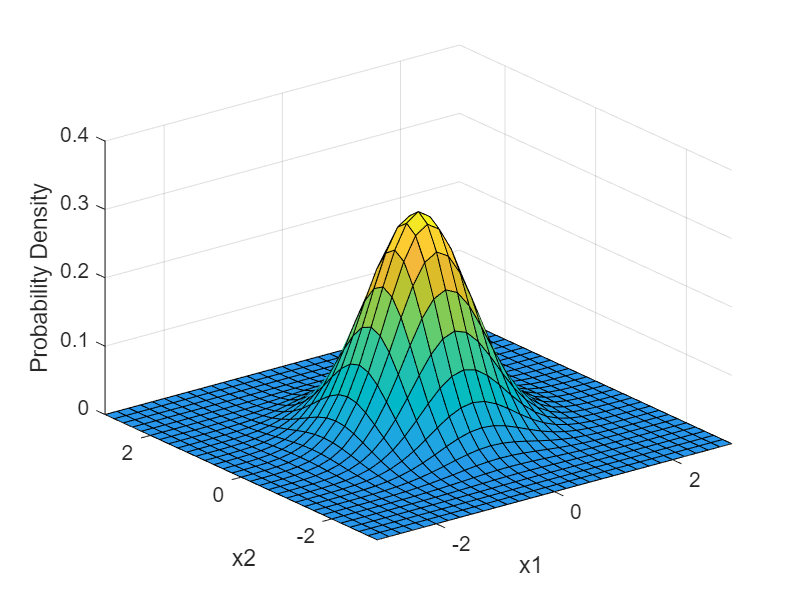

clear;clc;close;

mu = [0 0];
Sigma = [0.5 0.0;0.0 0.5];

x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y);
clim([min(y(:))-0.5*range(y(:)),max(y(:))]);
axis([-3 3 -3 3 0 0.4]);
xlabel('x1');
ylabel('x2');
zlabel('Probability Density');

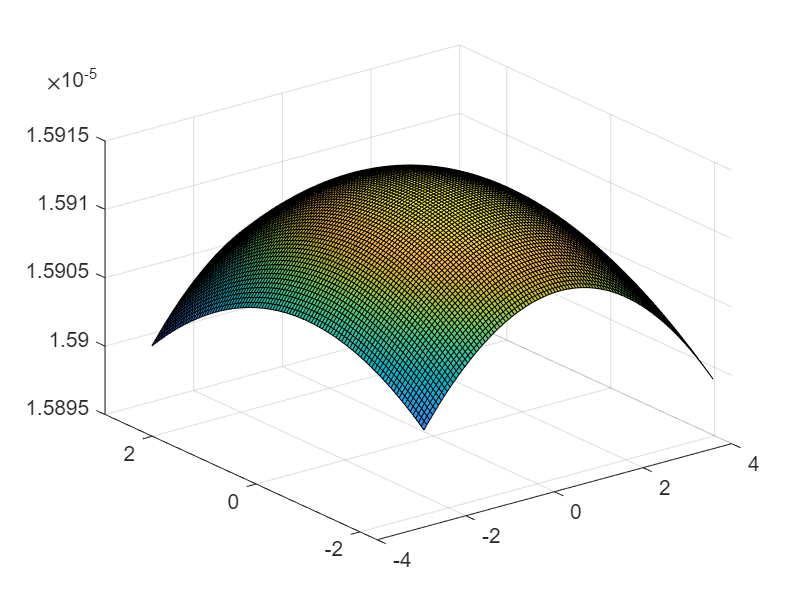

% generate some sample data
x = randn(100,1);
y = randn(100,1);

% create a grid of points to evaluate the density
xgrid = linspace(min(x), max(x), 100);
ygrid = linspace(min(y), max(y), 100);
[X,Y] = meshgrid(xgrid, ygrid);
xy = [X(:) Y(:)];

% estimate the density using a Gaussian kernel
k = 100;  % bandwidth parameter
f = ksdensity([x y], xy, 'Bandwidth', k);

% plot the density surface
surf(X, Y, reshape(f, size(X)));

# Detecting Probability of points in FoV

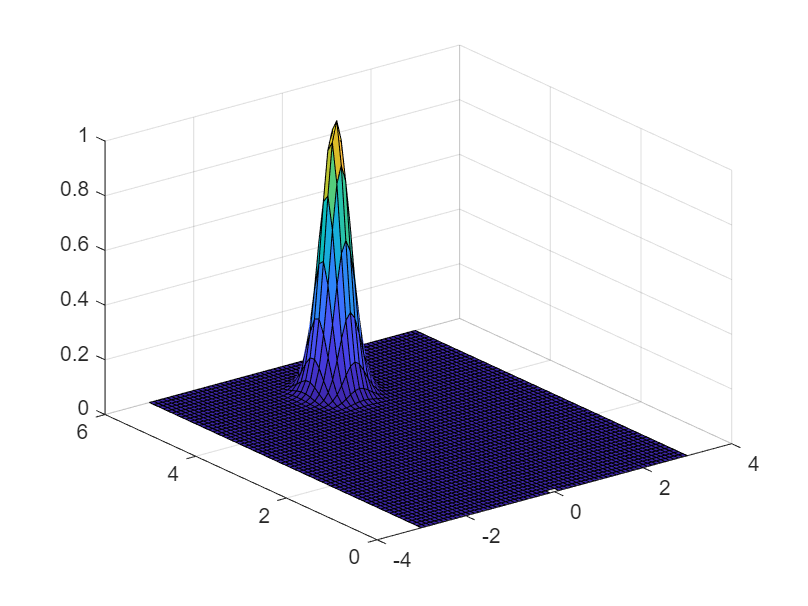

clear;clc;close;

pos = [0;0];
x1 = -3:0.1:3;
x2 = 0:0.1:6;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)]';

perspective = [0;1]; perspective = perspective/norm(perspective);
AOV = pi/6; alpha = AOV*0.5; range = 5;

d = vecnorm(X - pos); a =  acos( ((X - pos)./d)'*perspective );
y = exp( -( d - range*cos(alpha)).^2./(2*(range*cos(alpha)^2)*0.1^2) ).*exp( -(a.^2)./(2*alpha^2*0.2^2) )';
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y);

# Probability of points on the boundary of FoV

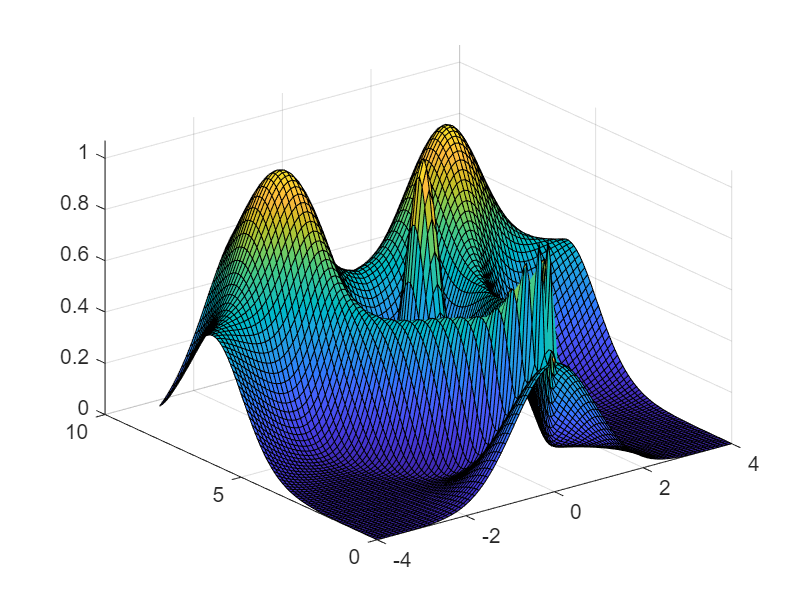

clear;clc;close;

pos = [0;0];
x1 = -4:0.1:4;
x2 = 0:0.1:8;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)]';

perspective = [0;1]; perspective = perspective/norm(perspective);
AOV = pi/6; alpha = AOV*0.5; range = 5; lambda = 2; range_max = ( (lambda+1)/lambda )*range*cos(alpha);

d = vecnorm(X - pos); a =  acos( ((X - pos)./d)'*perspective );

y1 = exp( -( d - range*cos(alpha)).^2./(2*(range*cos(alpha)^2)*0.2^2) ).*exp( -(a.^2)./(2*alpha^2*0.2^2) )';
y2 = exp( -( abs(d - 0.5*range_max) - 0.5*range_max ).^2./(2*(0.5*range_max)^2*0.25^2) ) + exp( -(abs(a) - alpha).^2./(2*alpha^2*0.35^2) )'...
   + exp( -( d - 0.5*range).^2./(2*(0.5*range^2)*0.3^2) ).*exp( -(a.^2)./(2*alpha^2*0.5^2) )';
y2 = (y2 - min(y2))./(max(y2)-min(y2));
y = y1 + y2;

Y1 = reshape(y1,length(x2),length(x1));
Y2 = reshape(y2,length(x2),length(x1));
Y = reshape(y,length(x2),length(x1));

% surf(x1, x2, Y1);
% surf(x1, x2, Y2);
surf(x1, x2, Y);